raw_data = readtable('lab_2_part_3.csv');

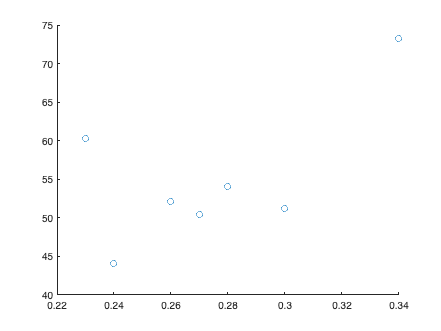


proccessed_data = get_diff_from_fit(raw_data.Time_s_1_11, raw_data.Angle_ChP2_rad_1_11, @(x) cos(3.96*x + 1.665), 0.34);
proccessed_data = [proccessed_data; get_diff_from_fit(raw_data.Time_s_Run1, raw_data.Angle_ChP2_rad_Run1, @(x) cos(3.81*x + 3), 0.27)];
proccessed_data = [proccessed_data; get_diff_from_fit(raw_data.Time_s_Run_2, raw_data.Angle_ChP2_rad_Run_2, @(x) cos(3.93*x - 0.54), 0.3)];
proccessed_data = [proccessed_data; get_diff_from_fit(raw_data.Time_s_Run_4, raw_data.Angle_ChP2_rad_Run_4, @(x) cos(3.9*x - 0.43), 0.28)];
proccessed_data = [proccessed_data; get_diff_from_fit(raw_data.Time_s_Run_5, raw_data.Angle_ChP2_rad_Run_5, @(x) cos(3.9*x + 0.25), 0.26)];
proccessed_data = [proccessed_data; get_diff_from_fit(raw_data.Time_s_Run_6, raw_data.Angle_ChP2_rad_Run_6, @(x) cos(3.9*x - 2.72), 0.24)];
proccessed_data = [proccessed_data; get_diff_from_fit(raw_data.Time_s_Run_7, raw_data.Angle_ChP2_rad_Run_7, @(x) cos(3.9*x - 3), 0.23)];
scatter(proccessed_data.height, proccessed_data.diff)

fit_for_line(proccessed_data.height, proccessed_data.diff, zeros(1, length(proccessed_data.diff)))

ans =      Linear model Poly1:
     ans(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =         196
       p2 =           0  (fixed at bound)

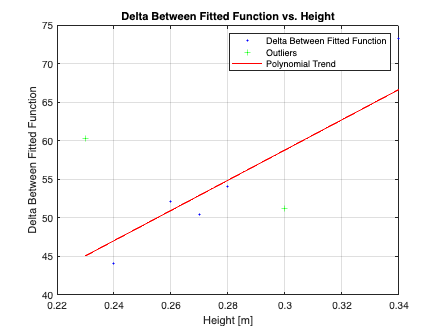

cftool(proccessed_data.height, proccessed_data.diff, [], zeros(1, length(proccessed_data.height)))
title("Delta Between Fitted Function vs. Height")

function diff_table=get_diff_from_fit(x_vals, y_vals, input_function, height)
    [x_vals_fixed, y_vals_fixed] = preprocess_data(x_vals, y_vals);
    function_vals = arrayfun(input_function, x_vals_fixed);
    diff = (sum((function_vals - y_vals_fixed).^2))^0.5;
    diff_table = table(height, diff);
end

function [time_vals, angle_vals_minus_mean]=preprocess_data(x_vals, y_vals)
    time_vals = rmmissing(x_vals);
    angle_vals = rmmissing(y_vals);
    smallest_input = min(length(time_vals), length(angle_vals));
    time_vals = time_vals(1:smallest_input);
    angle_vals = angle_vals(1:smallest_input);
    angle_vals_minus_mean = (angle_vals - mean(angle_vals));
    angle_vals_minus_mean = angle_vals_minus_mean ./ max(angle_vals_minus_mean);
    % cftool(time_vals, angle_vals_minus_mean, [], zeros(1, length(time_vals)))
end